% Load the Simulink model from .slx file
load_system('travelling_wind.slx')

% Set the simulation stop time to 10 seconds
set_param('travelling_wind', 'StopTime', '10')

% Run the simulation
simOut = sim('travelling_wind');

% Get the output from the workspace
output = simOut.get('output');

% Close the system after the simulation
close_system('travelling_wind')

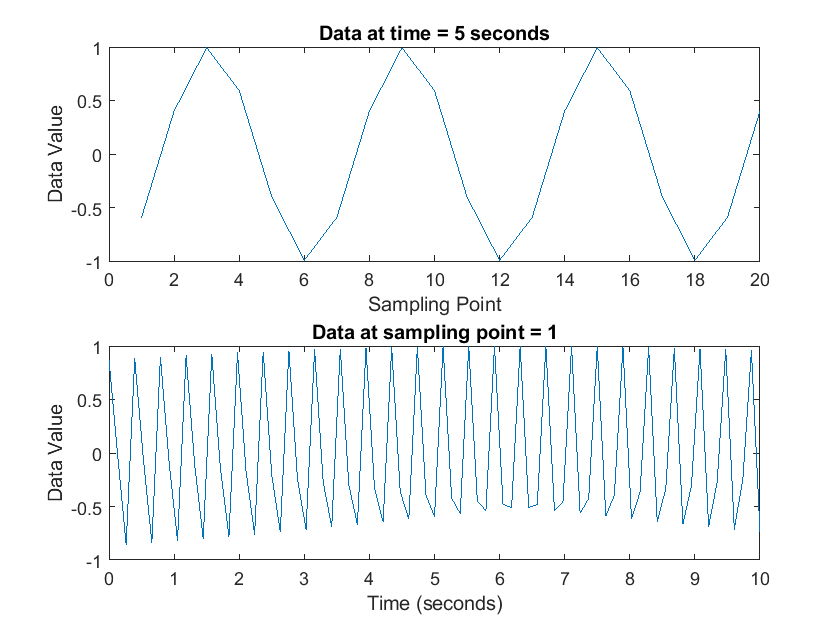

% Get time and data from timeseries
time_points = output.time;
data_matrix = output.data;

% Number of sampling points
num_sampling_points = size(data_matrix, 2);
sampling_points = 1:num_sampling_points; % Assuming your sampling points are integers from 1 to number of points

% Select a time (in seconds) to plot
selected_time = 5; % change this to your desired time
[~, time_index] = min(abs(time_points - selected_time));
selected_time_data = data_matrix(time_index, :);

% Select a sampling point to plot over time
selected_sampling_point = 1; % change this to your desired sampling point
[~, point_index] = min(abs(sampling_points - selected_sampling_point));
selected_point_data = data_matrix(:, point_index);

% Now, create the plots
figure;

% Plot data at selected time over all sampling points
subplot(2, 1, 1);
plot(sampling_points, selected_time_data);
xlabel('Sampling Point');
ylabel('Data Value');
title(['Data at time = ', num2str(selected_time), ' seconds']);

% Plot data over time for the selected sampling point
subplot(2, 1, 2);
plot(time_points, selected_point_data);
xlabel('Time (seconds)');
ylabel('Data Value');
title(['Data at sampling point = ', num2str(selected_sampling_point)]);